# RST control of the gantry crane

Using RST design with incremental controller.

The model is 6th order obtained with system identification.

The Diophantine equation becomes

$A(z)(z-1)R(z) + B(z)S(z) = A_{c}(z)A_o(z)  $.

 The Diophantine equation will give $\deg(A) + \deg(R) + 1$ linear equations, and the number of unknown parameters in the controller


$$F_b(z) = \frac{s_0z^{n+1} + s_1z^{n} + \cdots + s_{n+1}}{(z-1)(z^n + r_1z^{n-1} + \cdots + r_n)}$$


is $n+n+2=2\deg R + 2$.

Setting the number of equations equal to the number of unknown parameters gives

$\deg{R} = \deg{A} +1-2 = \deg{A} - 1 = 5
$.

Hence, the controller is

$F_b(z) = \frac{s_0z^6 + s_1z^5 + s_2z^4+s_3z^3 + s_4z^2 + s_5z + s_6}{(z-1)(z^5+r_1z^4 + r_2z^3 + r_3 z^2 + r_4 z + r_5)}$.

The LHS of the Diophantine equation is of degree 12. We can choose six oberver poles (in the origin) and six closed-loop poles.

% Kjartan Halvorsen 
% 2021-07-20


% Load model
% 
load('/home/kjartan/tec/mr2007-computerized-control/system-identification/matlab/crane-sysid-results.mat')

h = 0.2;
H = tf(B, A, h);


## Design

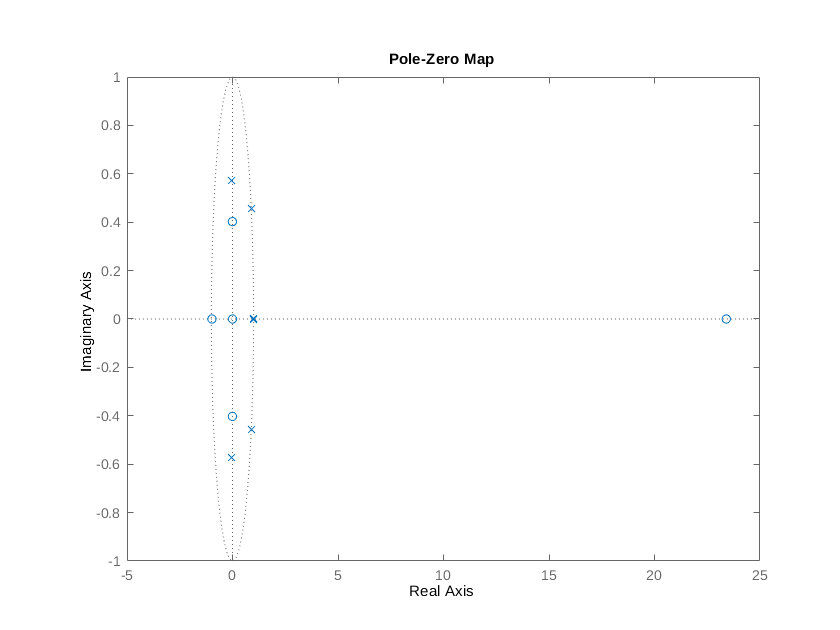


% For symbolic computations
syms z
As = poly2sym(A, z); % Generates polynomial A(1)*z^nA + A(2)*z^(nA-1) + ...
Bs = poly2sym(B, z);

pzmap(H)











% Desired characteristic polynomial
p1 = 0.8;
p2 = 0.8;
p3 = 0.8+0.1*1j;
p4 = conj(p3);
p5 = 0.8+0.2*1j;
p6 = conj(p5);

Acs = (z-p1)*(z-p2)*(z-p3)*(z-p4)*(z-p5)*(z-p6);

% Observer pole
p0 = 0;
Aos = (z-p0)*(z-p0)*(z-p0)*(z-p0)*(z-p0)*(z-p0);


## Solve


% Controller polynomials
r = [1, sym('r', [1, 5])]

$$r = \left(\begin{array}{cccccc} 1 & r_{1} & r_{2} & r_{3} & r_{4} & r_{5} \end{array}\right)$$

s = sym('s', [1, 6]); % Vector starts with s1
s = cat(2, sym('s0'), s) % Now it starts with s0

$$s = \left(\begin{array}{ccccccc} s_{0} & s_{1} & s_{2} & s_{3} & s_{4} & s_{5} & s_{6} \end{array}\right)$$

Rs = poly2sym(r, z);
Ss = poly2sym(s, z);
    

% Left hand side of Diophantine eqn
disp('Left hand side of Diophantine eqn')

Left hand side of Diophantine eqn


LHS = collect(As*(z-1)*Rs + Bs*Ss, z)


% Right hand side

disp('Right hand side of Diophantine eqn')

Right hand side of Diophantine eqn


RHS = collect(Acs*Aos, z)

$$RHS = z^{12}-\frac{24\,z^{11}}{5}+\frac{193\,z^{10}}{20}-\frac{52\,z^{9}}{5}+\frac{15841\,z^{8}}{2500}-\frac{6466\,z^{7}}{3125}+\frac{884\,z^{6}}{3125}$$


% Coefficients
LHScoeffs = coeffs(LHS, z, 'All'); % Coefficients in increasing power of z
RHScoeffs = coeffs(RHS, z, 'All');

% Set up system of equations and solve
unknowns = cat(2, r(2:end), s);
sol = solve(LHScoeffs(2:end) - RHScoeffs(2:end), unknowns); %

% Find t0 as Ac(1)/B(1)
t0 = subs(Acs, z, 1) / subs(Bs, z, 1);

% Substitute numerical values

s0_n = double(sol.s0);
s1_n = double(sol.s1);
s2_n = double(sol.s2);
s3_n = double(sol.s3);
s4_n = double(sol.s4);
s5_n = double(sol.s5);
s6_n = double(sol.s6);
r1_n = double(sol.r1);
r2_n = double(sol.r2);
r3_n = double(sol.r3);
r4_n = double(sol.r4);
r5_n = double(sol.r5);

t0_n = double(t0);

R_c = conv([1, -1], [1, r1_n, r2_n, r3_n, r4_n, r5_n]);
S_c = [s0_n, s1_n, s2_n, s3_n, s4_n, s5_n, s6_n];
T_c = t0_n*double(coeffs(Aos, z, 'All')) 

T_c =   548.2064         0         0         0         0         0         0




% Define the controller
F_fb_c = tf(S_c, R_c, h);
F_ff_c = tf(T_c, R_c, h);

% Closed-loop system from command signal to output
Hc_c = minreal(F_ff_c * feedback(H, F_fb_c))

Hc_c =
 
                             -3.089e-06 z^9 + 6.926e-05 z^8 + 7.054e-05 z^7 + 1.19e-05 z^6 + 1.139e-05 z^5
  -----------------------------------------------------------------------------------------------------------------------------------
  z^10 - 4.8 z^9 + 9.65 z^8 - 10.4 z^7 + 6.336 z^6 - 2.069 z^5 + 0.2829 z^4 + 1.665e-16 z^3 + 2.275e-23 z^2 + 2.776e-17 z - 1.388e-17
 
Sample time: 0.2 seconds
Discrete-time transfer function.




% Closed-loop system from command signal to control signal
Huc_c = minreal(F_ff_c * feedback(1, H*F_fb_c));

% Closed-loop system from disturbance signal to output
Hvc_c = minreal(feedback(1, H*F_fb_c));


## Plot responses

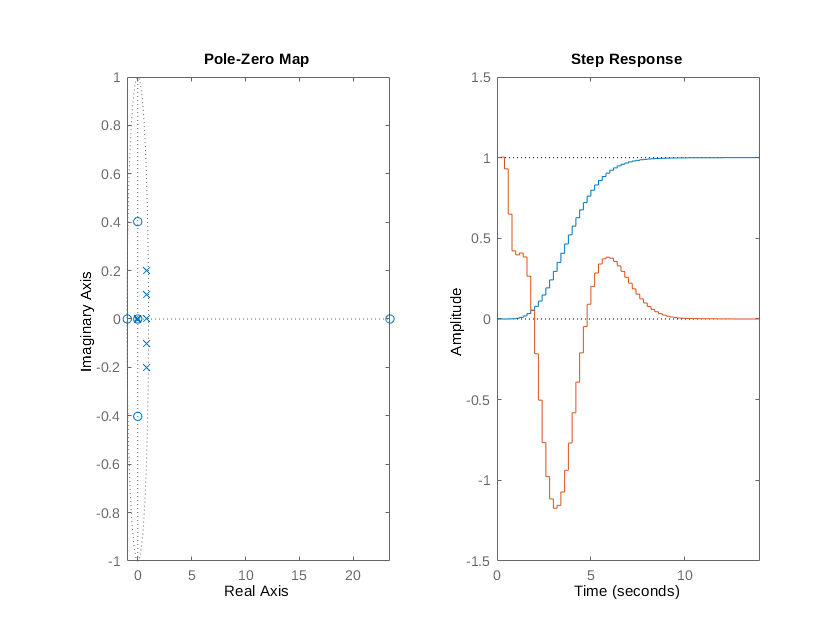


figure()
clf
subplot(121)
pzmap(Hc_c)
subplot(122)
step(Hc_c, Hvc_c)

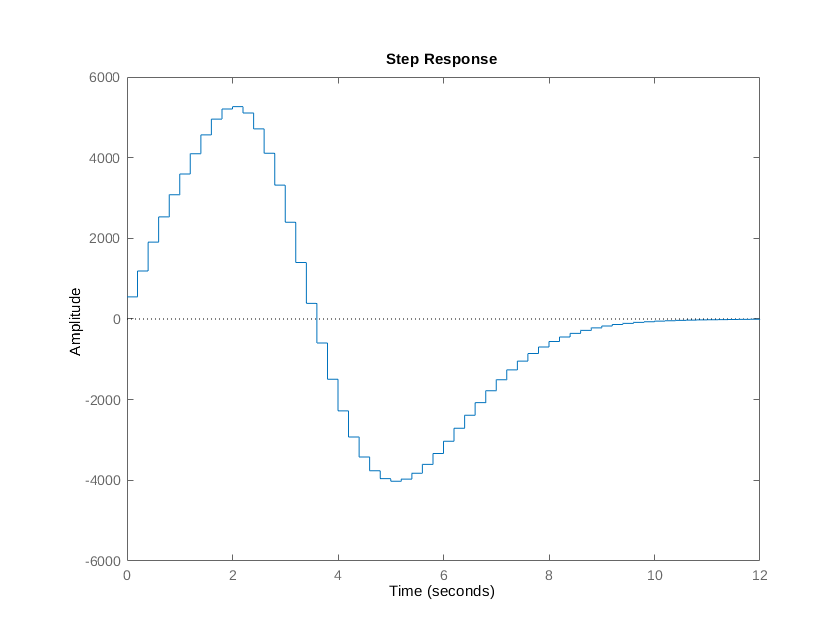

figure()
step(Huc_c)